# Create Rotational Transformation Matrix from Axis-Angle Representation of Rotation in Space

## obvious solution

% https://de.mathworks.com/help/robotics/ref/axang2rotm.html

function doesn't accept syms data type

## Definition

syms C ga B f_WSTrad phi
% C = f_WSTrad * B
phi = -C+ga;

Rotation of angle phi around z-axis

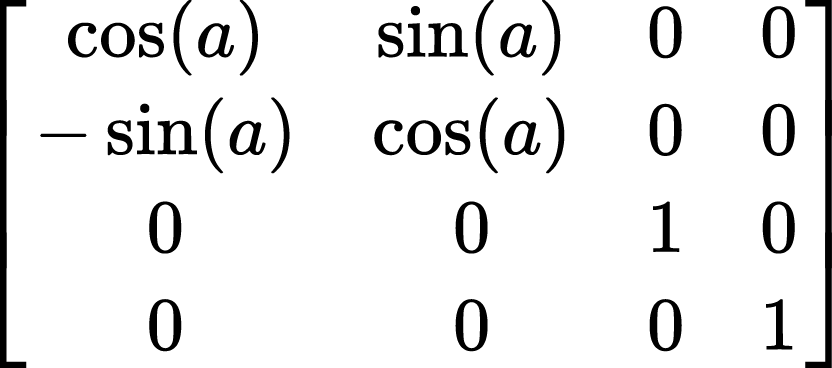

### Hardcode

R_Cga= [cos(phi) -sin(phi) 0 0; sin(phi) cos(phi) 0 0; 0 0 1 0; 0 0 0 1]

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### axang2rotm

multiple dimensional call

ax = [0, 0, 1; 1, 0, 0];
ang = [phi;phi];
% rotm = dim4(axang2rtm(ax,ang),2,'forward')

call using the shortcuts

rotm = axang2rtm('zxy',[phi;phi;phi])

$$\left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0\\ 0 & -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & 0 & -\sin\left(C-\mathrm{ga}\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(C-\mathrm{ga}\right) & 0 & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

rotm = dim4(axang2rtm("zxy",phi),2,'forward')

$$\left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0\\ 0 & -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & 0 & -\sin\left(C-\mathrm{ga}\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(C-\mathrm{ga}\right) & 0 & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Using a dedicated function

R_Cga = dim4(localaxang2rtm([0,0,1],phi),2,'forward')

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Using a rotated vector

kvec = [0;0;1];     % unit vector of rotation axis
vvec = [1;0;0];     % unit vector of direction in R^3
vrot = vvec*cos(phi) + (cross(kvec,vvec))*sin(phi) + kvec*dot(kvec,vvec)*(1-cos(phi));
R_Cga = vec2rot(vrot,[0,0,1]);

### Development of private function

function RTM = localaxang2rtm(ax,ang)
    

Formula found [here](https://en.wikipedia.org/wiki/Rotation_matrix#Rotation_matrix_from_axis_and_angle):

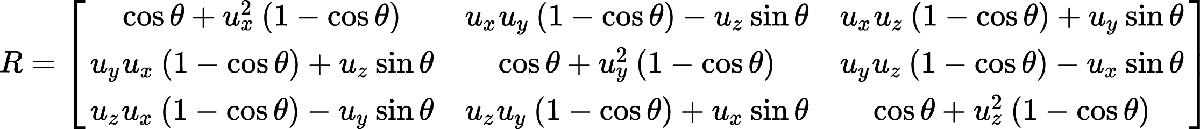

    RTM = [cos(ang) + ax(1)^2*(1-cos(ang)),          ax(1)*ax(2)*(1-cos(ang))-ax(3)*sin(ang), ax(1)*ax(3)*(1-cos(ang)) + ax(2)*sin(ang);...
           ax(2)*ax(3)*(1-cos(ang))+ ax(3)*sin(ang), cos(ang) + ax(2)^2*(1-cos(ang)),         ax(2)*ax(3)*(1-cos(ang)) - ax(1)*sin(ang);...
           ax(3)*ax(1)*(1-cos(ang))-ax(2)*sin(ang),  ax(3)*ax(2)*(1-cos(ang))+ax(1)*sin(ang), cos(ang)+ ax(3)^2*(1-cos(ang))];
end